## Group Assignment 2 - Image as a function, Image as a matrix, Convolution, etc.

1) You need 2 images. You can take new images or use your previous images. (a suggestion: try to use images where you think you will see something new in different color spaces).

% import images
miranda = imread('../images/IMAGE012.jpg');
computer = imread('../images/IMAGE001.jpg');

### Pixel Processing (Jiayuan)

- Change brightness of your image

- Change contrast of your image

- Change brightness of alternating pixels of the image

### Color Spaces (Miranda)

- Show your images in the different color spaces we discussed. 

- Plot at least 4 different histograms  for each image from the various color spaces (e.g. you can do red,  green, saturation, value). 

- Were these color spaces useful for  your chosen image? Did they show something that you would not see in a  color or grayscale image? Did the histograms show something useful?

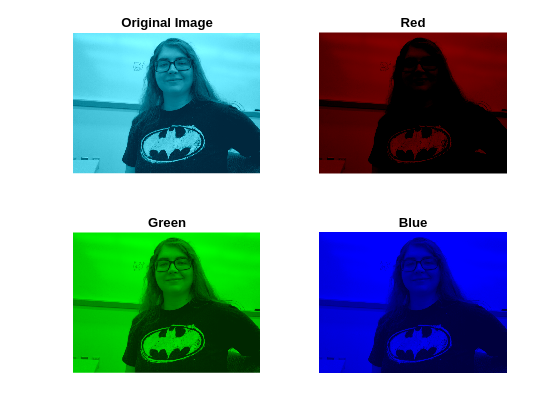

figure;
subplot(2,2,1);
imshow(miranda);
title('Original Image')

subplot(2,2,2);
miranda_R = miranda;
miranda_R(:,:,2) = 0;
miranda_R(:,:,3) = 0;
imshow(miranda_R);
title('Red')

subplot(2,2,3);
miranda_G = miranda;
miranda_G(:,:,1) = 0;
miranda_G(:,:,3) = 0;
imshow(miranda_G);
title('Green')

subplot(2,2,4);
miranda_B = miranda;
miranda_B(:,:,1) = 0;
miranda_B(:,:,2) = 0;
imshow(miranda_B);
title('Blue')

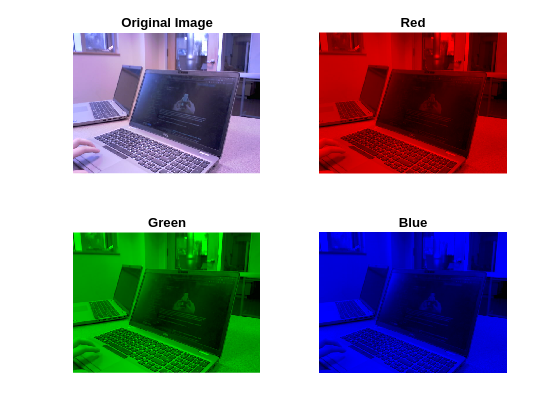


figure;
subplot(2,2,1);
imshow(computer);
title('Original Image')

subplot(2,2,2);
computer_R = computer;
computer_R(:,:,2) = 0;
computer_R(:,:,3) = 0;
imshow(computer_R);
title('Red')

subplot(2,2,3);
computer_G = computer;
computer_G(:,:,1) = 0;
computer_G(:,:,3) = 0;
imshow(computer_G);
title('Green')

subplot(2,2,4);
computer_B = computer;
computer_B(:,:,1) = 0;
computer_B(:,:,2) = 0;
imshow(computer_B);
title('Blue')

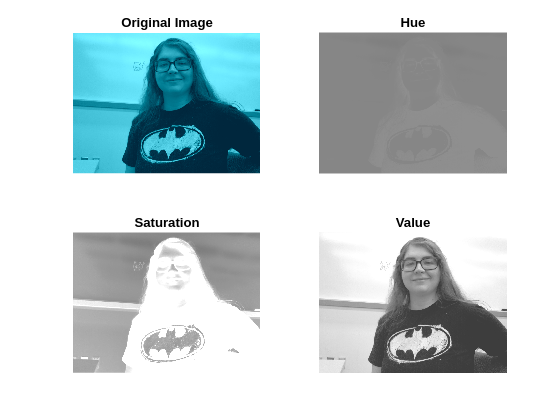

[h, s, v] = rgb2hsv(miranda);

figure;
subplot(2,2,1);
imshow(miranda);
title('Original Image')

subplot(2,2,2);
imshow(h);
title('Hue')

subplot(2,2,3);
imshow(s);
title('Saturation')

subplot(2,2,4);
imshow(v);
title('Value')

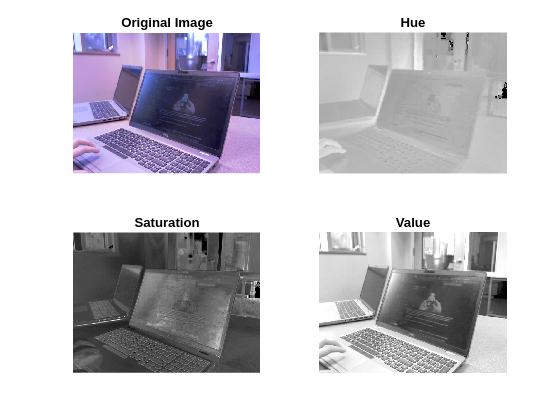

[h, s, v] = rgb2hsv(computer);

figure;
subplot(2,2,1);
imshow(computer);
title('Original Image')

subplot(2,2,2);
imshow(h);
title('Hue')

subplot(2,2,3);
imshow(s);
title('Saturation')

subplot(2,2,4);
imshow(v);
title('Value')

### Convolution/linear filtering (Gia)

Again, use 2 images - these can be same as before or different - your choice

Apply identity filter to both images, show results

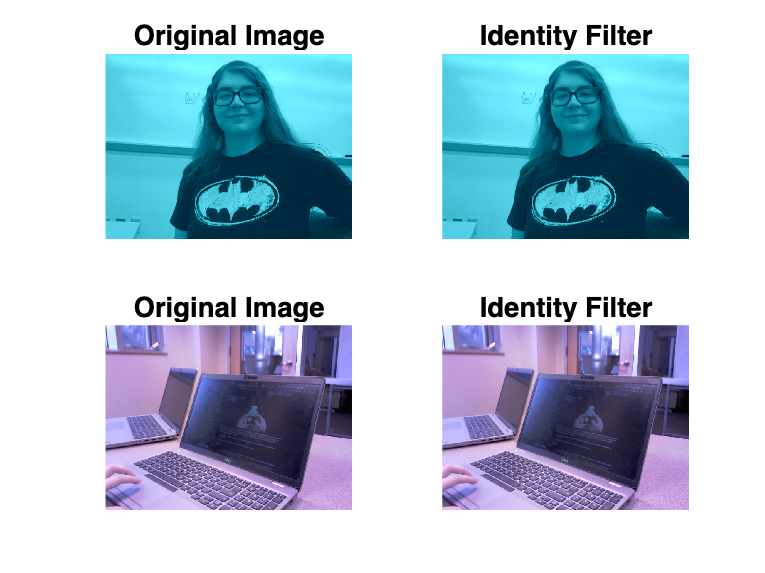

% Identity Filter
I = [0, 0, 0; 0, 1, 0; 0, 0, 0]; % identity filter

figure;
subplot(2,2,1);
imshow(miranda);
title('Original Image')

subplot(2,2,2);
miranda_I = imfilter(miranda, I, 'conv');
imshow(miranda_I);
title('Identity Filter')

subplot(2,2,3);
imshow(computer);
title('Original Image')

subplot(2,2,4);
computer_I = imfilter(computer_I, I, 'conv');
imshow(computer_I);
title('Identity Filter')

Apply box filter of 2 different sizes to both images, show results (that would be 4 images). 

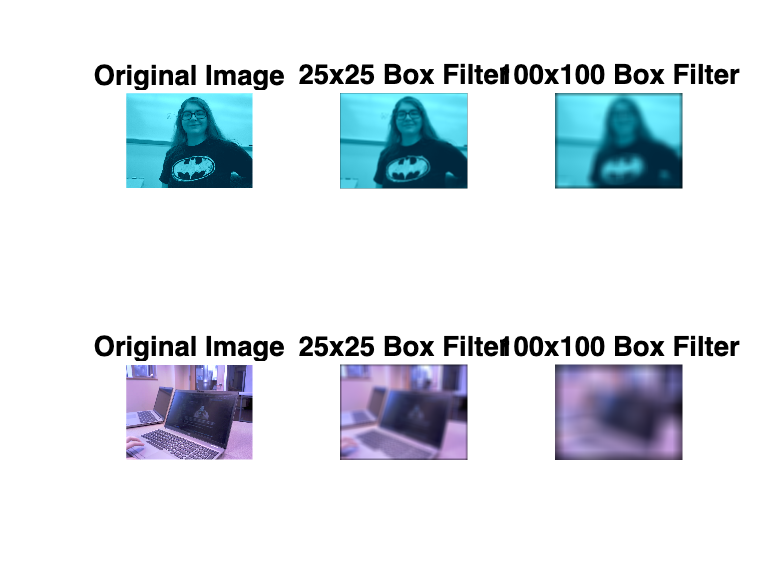

% Box Filter
size = 25;
size2 = 100;

B = 1/size^2 * ones(size); 
B2 = 1/size2^2 * ones(size2);

figure;
subplot(2,3,1);
imshow(miranda);
title('Original Image')

subplot(2,3,2);
miranda_B = imfilter(miranda, B, 'conv');
imshow(miranda_B);
title('25x25 Box Filter')

subplot(2,3,3);
miranda_B2 = imfilter(miranda, B2, 'conv');
imshow(miranda_B2);
title('100x100 Box Filter')

subplot(2,3,4);
imshow(computer);
title('Original Image')

subplot(2,3,5);
computer_B = imfilter(computer, B, 'conv');
imshow(computer_B);
title('25x25 Box Filter')

subplot(2,3,6);
computer_B2 = imfilter(computer, B2, 'conv');
imshow(computer_B2);
title('100x100 Box Filter')

Box filter was a blurring filter. Think about what a sharpening filter would look like and apply it to your 2 images.

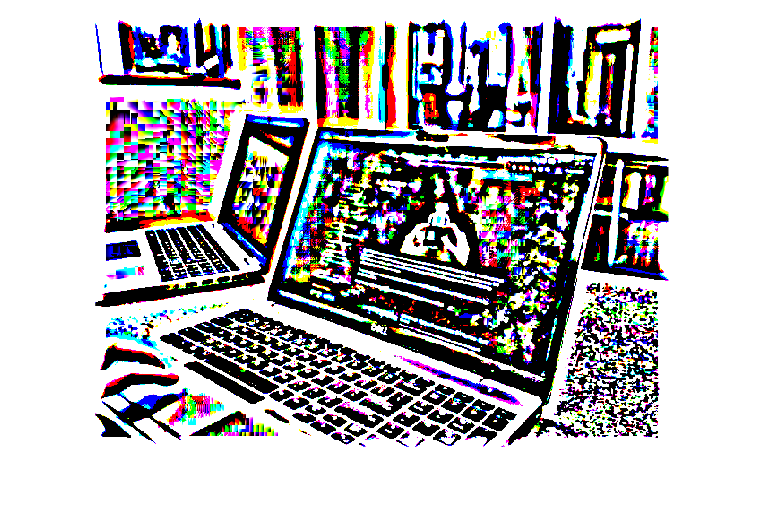

S2 = -1 * ones(size);
S2(13,13) = 25^2; 

computer_S = imfilter(computer, S2, 'conv');
figure;
imshow(computer_S);

Design a Gaussian filter with your  choice of variance. Apply this to your 2 images. Please mention what  variance you used in the image. 

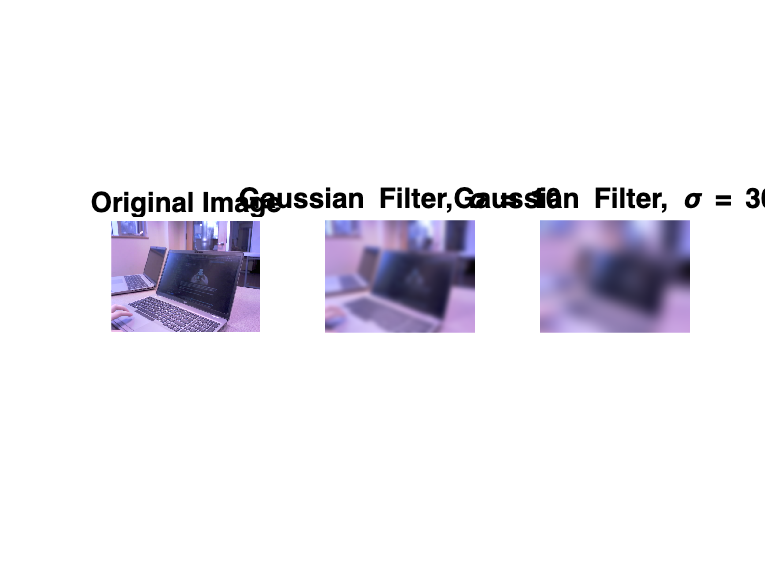

% Gaussian Filter
std = 10;
std2 = 30; % approximates miranda's myopia

figure;
subplot(1,3,1)
imshow(computer);
title('Original Image')

subplot(1,3,2)
computer_G = imgaussfilt(computer, std);
imshow(computer_G);
title('Gaussian Filter, \sigma = 10')

subplot(1,3,3)
computer_G2 = imgaussfilt(computer, std2);
imshow(computer_G2);
title('Gaussian Filter, \sigma = 30')

Bonus: Bit Plane Extraction

% % conversting to bitplane
% c0 = mod(cd, 2);
% c1 = mod(floor(cd/2), 2);
% c2 = mod(floor(cd/4), 2);
% c3 = mod(floor(cd/8), 2);
% c4 = mod(floor(cd/16), 2);
% c5 = mod(floor(cd/32), 2);
% c6 = mod(floor(cd/64), 2);
% c7 = mod(floor(cd/128), 2);
% 
% % reconstituted image
% cc = 2*(2*(2*(2*(2*(2*(2*c7+c6)+c5)+c4)+c3)+c2)+c1)+c0
